# Wake drag Calculation

this will first load the data and then seperate in usefull tables

% Import data from text file
data = readtable("C:\Users\MichaelGerits\OneDrive - Delft University of Technology\Documenten\Academia\Study material\Bsc 2\AE2130-II Wind tunnel practical\wakeDragCalc\raw_testG82D.txt");
data(1,:) = []; %Removes the first row
columnNames = data.Properties.VariableNames;

hysterisis = false;%choose if the go back angles are included or not.
if hysterisis==false %remove the hysterisis datapoints if wanted
    data(21:end,:) = [];
end
display(data)

data = 20×121 table
    Run_nr      Time      Alpha    Delta_Pb    P_bar       T       rpm       rho      P001       P002       P003       P004       P005       P006       P007       P008       P009       P010       P011       P012       P013       P014       P015       P016       P017       P018       P019       P020       P021       P022       P023       P024       P025      P026       P027       


c = 160*1e-3;

get the total pressure values


startIndex = find(strcmp(columnNames, 'P098'));
endIndex = find(strcmp(columnNames, 'P109'));

statP = table2array(data(:, startIndex:endIndex)); %Pa

Get the static pressure values

startIndex = find(strcmp(columnNames, 'P050'));
endIndex = find(strcmp(columnNames, 'P096'));

totP = table2array(data(:, startIndex:endIndex));%Pa

get other miscaenious values (rho, delp...etc)

rho = data.rho; %kg/m³
DelP = data.Delta_Pb; %Pa
alpha = data.Alpha; %deg
totPtun = data.P097;%Pa

## Reshape static 

The static pressure matrix will be reshaped to th same shape as the total pressure one by copying the collumns at the corrseponding y position, since its intervals are larget than the total ones

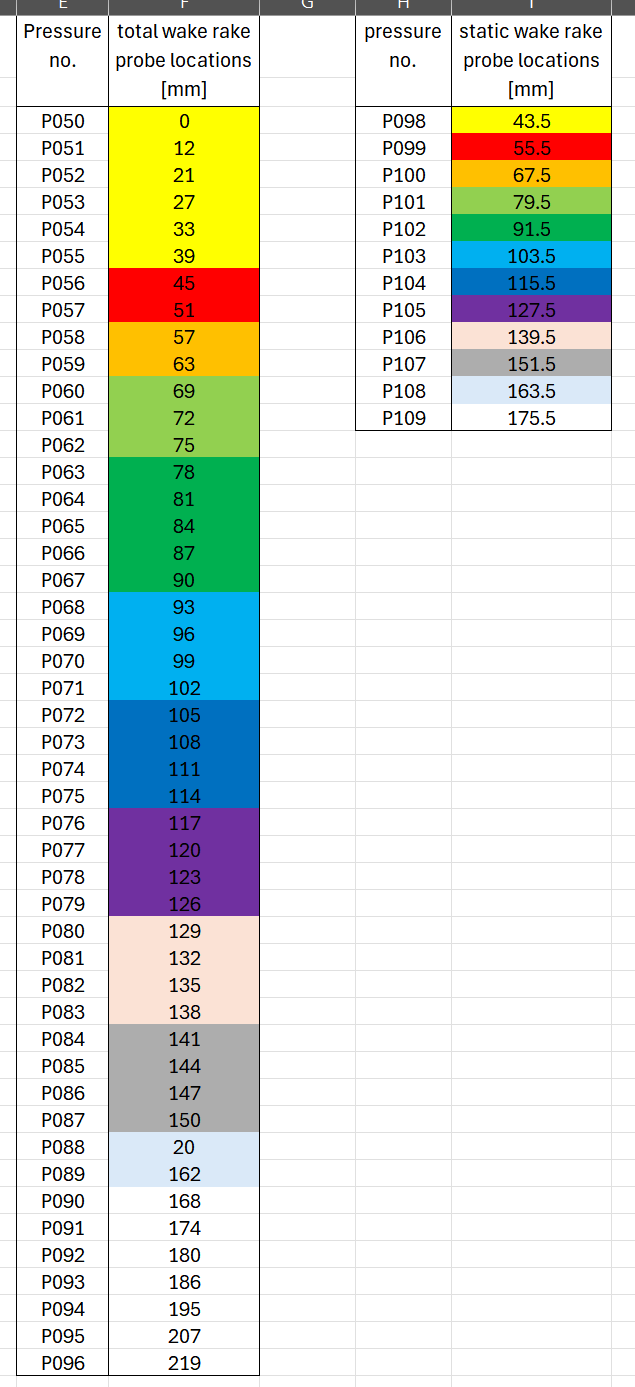

totPos = [0, 12, 21, 27, 33, 39, 45, 51, 57, 63, 69, 72, 75, 78, 81, 84, 87, 90, 93, 96, 99, 102, 105, 108, 111, 114, 117, 120, 123, 126, 129, 132, 135, 138, 141, 144, 147, 150, 156, 162, 168, 174, 180, 186, 195, 207, 219];%mm
statPos = [43.5, 55.5, 67.5, 79.5, 91.5, 103.5, 115.5, 127.5, 139.5, 151.5, 163.5, 175.5];%mm

[m,n] = size(totP);
placeholder = zeros(m,n);


### reshaping

% Initialize tracking variable to iterate through total rake locations
tcol = 1; % MATLAB indices start at 1

% Iterate through the static rake locations
for scol = 1:length(statPos)
    % While the current total rake position is <= the current static position
    while tcol <= length(totPos) && totPos(tcol) <= statPos(scol)
        placeholder(:,tcol) = statP(:,scol); % Copy the static value
        tcol = tcol + 1; % Move to the next total rake position
    end
end

% Fill in remaining columns beyond the last static position
for i = tcol:length(totPos)
    placeholder(:,i) = statP(:,end); % Use the last static value
end

% Replace or assign the output as needed
statP = placeholder;

with these we can now get the matrix of dynamic pressure by simply subtracting

dynP = totP - statP;

## Get windtunnel pressures

dynPtun = 0.211804 + 1.928442 .* data.Delta_Pb + (1.879374e-4) * (data.Delta_Pb.^2);

since the static pressure readings are nonsensical, This will be obtained by subtracting the dynamic pressure from the total one (this should not be affected by the airfoil, as the entire process at these speeds is isentropic)

statPtun = totPtun-dynPtun;

### Small test section for the collumn division 

% m=5;
% n=10;
% A = randi([1, 10], m, n)
% col = (1:m)'
% 
% res = A./col

## Getting the respective velocities

each line in the wake plot represents a different angle of attack

vel = sqrt((2 .* dynP) ./ rho)

vel =    25.3881   25.4359   25.4041   25.3730   25.3931   25.4188   25.5226   25.5635   25.5039   25.4799   25.4933   25.4809   25.5222   25.4883   25.4726   25.4803   25.4552   25.4429   25.4979   25.5086   25.4101   24.9325   23.8581   22.4918   21.6593   21.9728   23.1408   24.4014   25.1416   25.3897   25.3485   25.3851   25.4436   25.4269   25.4456   25.4279   25.4479   25.4065   25.3931   25.4496   25.5994   25.6911   25.6438   25.6096   25.6169   25.6713   25.6511
   25.2969   25.3402   25.3140   25.2871   25.3023   25.3315   25.3509   25.3989   25.3348   25.3224   25.3469   25.3224   25.3774   25.3385   25.3248   25.3382   25.3221   25.3083   25.3147   25.3248   25.1769   24.5362   23.4742   22.7093   23.0712   24.2763   24.9462   25.2211   25.2834   25.2979   25.2417   25.2804   25.2925   25.3429   25.3164   25.2895   25.3039   25.2700   25.2592   25.3090   25.3771   25.4657   25.4173   25.3891   25.3932   25.4510   25.4320
   25.2279   25.2730   25.2430   25.2181   25.2296  

veltun = sqrt((2 .* dynPtun) ./ rho)

veltun =    25.0316
   24.9688
   24.9061
   25.0680
   25.0590
   24.8996
   25.0970
   25.0861
   24.9331
   25.1977


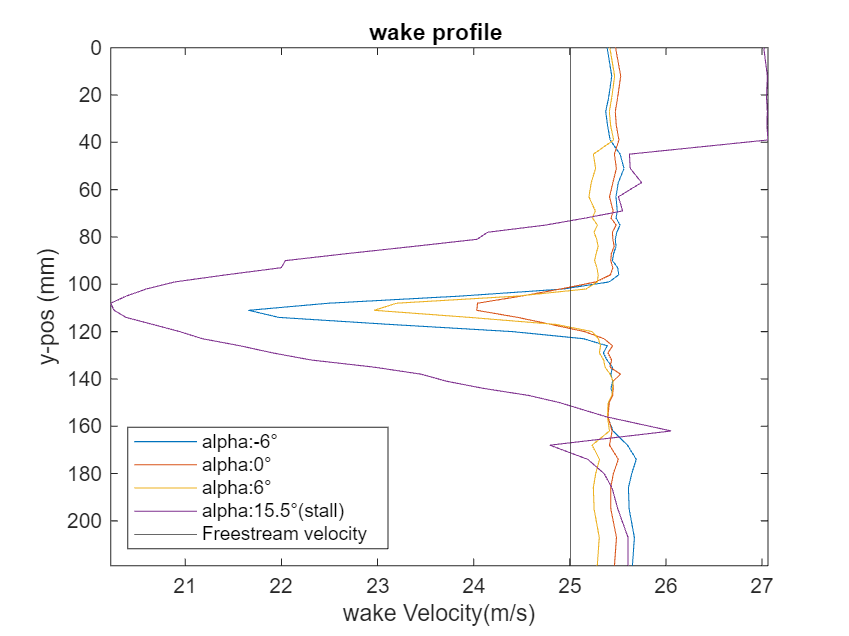



plot(vel([1,4,6,end],:)', totPos)
set(gca, 'YDir','reverse')
xline(mean(veltun))
xlabel('wake Velocity(m/s)')
ylabel('y-pos (mm)')
title('wake profile ')
legend(["alpha:-6°", "alpha:0°", "alpha:6°", "alpha:15.5°(stall)", "Freestream velocity"], Location="southwest")
axis tight;

## Get the velocity drag

dy = diff(totPos) * 1e-3;%m
D1 = 0;
for j =1:length(dy) %integrate with the discrete "bars" taking the leftmost value of the interval
    D1 = D1 + rho .* (veltun - vel(:,j))  .* vel(:,j) * dy(j);
end
CD1 = D1./(dynPtun * c);

## Get the pressure drag

D2 = 0;
for j =1:length(dy) %integrate with the discrete "bars" taking the leftmost value of the interval
    D2 = D2 + (statPtun - statP(:,j)) * dy(j);
end
CD2 = D2./(dynPtun * c);

## Get the total drag and plot

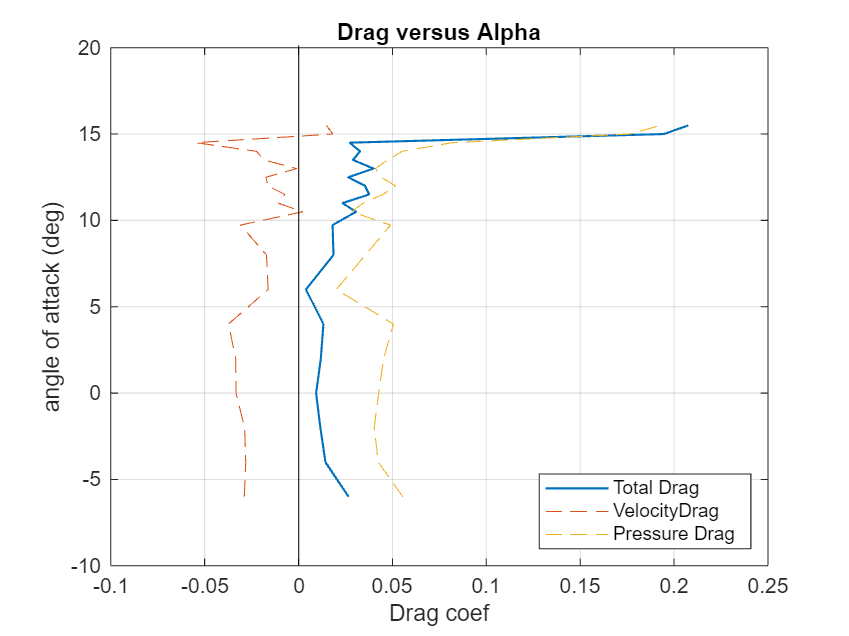

D = D1+D2;
CD = CD1+CD2;
plot(CD, alpha, "LineWidth",1)
xlabel('Drag coef')
ylabel('angle of attack (deg)')
title('Drag versus Alpha')
hold on
plot(CD1, alpha,"--")
plot(CD2, alpha,"--")
legend(["Total Drag", "VelocityDrag", "Pressure Drag"],'Location', 'southeast')
hold off

grid on

annotation("line", [0.3518 0.3518], [0.1109 0.9286])


display(mean(D))

    2.3741



## Save coef and alpha to csv files

% csvwrite("CD.csv", CD);
% csvwrite("CD_vel.csv", CD1);
% csvwrite("CD_pres.csv", CD2);
% csvwrite("alpha.csv", alpha);